close all;
% a = out.acceleration.Data
% b = normalize(out.pwm.data,"range")
% [len,~] = size(a);
% for i=1:len
%     if a(i) < -10
%         a(i) = 0;
%     end
% end
% hold on
% a = a
% plot(a)
% plot(b)s
% save('variable_a6.txt', 'a', '-ASCII');
% save('variable_b6.txt', 'b', '-ASCII');

a = out.Pose.Data

a =     0.0514   -1.9547    0.0160
    0.0515   -1.9547    0.0159
    0.0516   -1.9547    0.0158
    0.0514   -1.9546    0.0159
    0.0514   -1.9546    0.0159
    0.0514   -1.9546    0.0159
    0.0516   -1.9546    0.0158
    0.0517   -1.9547    0.0159
    0.0515   -1.9547    0.0156
    0.0515   -1.9547    0.0156


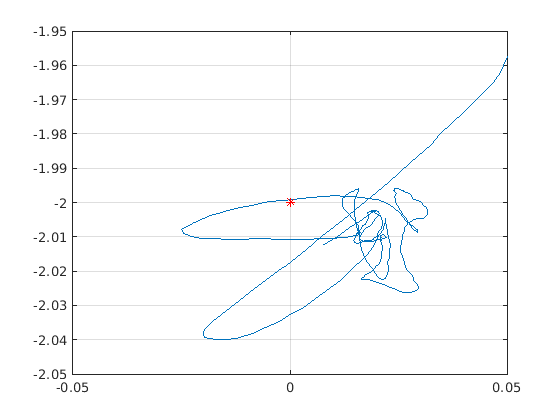

a = a(1:475,:);

%save('10_hover_3.txt', 'a', '-ASCII');
figure(1)
plot(a(:,1), a(:,2))
hold on
plot(0, -2, "r*")
xlim([-0.05 0.05])
ylim([-2.05 -1.95])
hold off
grid on 


b = a-[0, -2, 0.5]

b =     0.0514    0.0453   -0.4840
    0.0515    0.0453   -0.4841
    0.0516    0.0453   -0.4842
    0.0514    0.0454   -0.4841
    0.0514    0.0454   -0.4841
    0.0514    0.0454   -0.4841
    0.0516    0.0454   -0.4842
    0.0517    0.0453   -0.4841
    0.0515    0.0453   -0.4844
    0.0515    0.0453   -0.4844


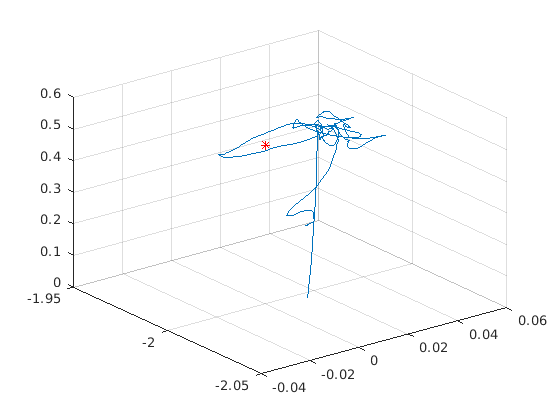


figure(2)
plot3(a(:,1), a(:,2), a(:,3), "LineStyle","-")
hold on
plot3(0, -2, 0.5, 'r*')
hold off
grid on 

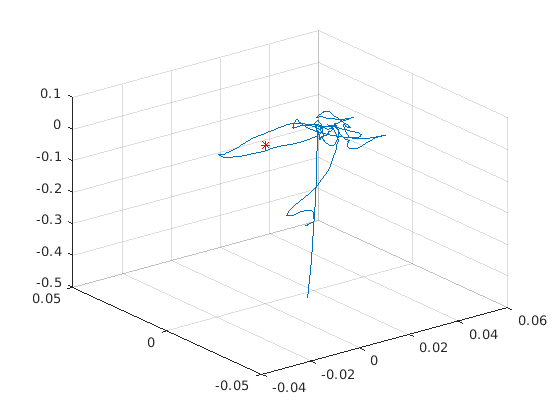



figure(3)
plot3(b(:,1), b(:,2), b(:,3), "LineStyle","-")
hold on
plot3(0, 0, 0, 'r*')
hold off
grid on 